# Análise de Resposta a Degrau e Identificação de Sistema (v9 - com Filtro Butterworth)



clear all;
close all;
clc;


## 1. Carregamento de Dados (Método Manual à Prova de Falhas)



filename = './cassio_dinamico2.txt';
if ~isfile(filename)
    error('Arquivo "%s" não encontrado. Verifique se ele está na mesma pasta que este script.', filename);
end
file_content = fileread(filename);
file_content = strrep(file_content, ',', '.');
lines = strsplit(file_content, '\n');
numeric_lines = lines(2:end);
numeric_lines = numeric_lines(~cellfun('isempty', numeric_lines));
numeric_text = strjoin(numeric_lines, '\n');
data_vector = sscanf(numeric_text, '%f');
num_columns = 7;
data = reshape(data_vector, num_columns, [])';
output = data(:, 1);
input = data(:, 3);
time_us = data(:, 6);
time_s = time_us / 1e6;


## 2. Segmentação Dinâmica dos Degraus (com Tempo)


step_indices = find(diff(input) ~= 0);
subidas_y = {}; subidas_t = {};
descidas_y = {}; descidas_t = {};
for i = 1:length(step_indices)
    start_idx = step_indices(i) + 1;
    if i == length(step_indices), end_idx = length(output); else, end_idx = step_indices(i+1); end
    if (end_idx - start_idx) < 15, continue; end
    segmento_y = output(start_idx:end_idx);
    segmento_t = time_s(start_idx:end_idx);
    segmento_t = segmento_t - segmento_t(1); 
    segmento_y = segmento_y - segmento_y(1);
    delta_input = input(start_idx) - input(start_idx-1);
    if delta_input > 0
        subidas_y{end+1} = segmento_y; subidas_t{end+1} = segmento_t;
    elseif delta_input < 0
        descidas_y{end+1} = segmento_y; descidas_t{end+1} = segmento_t;
    end
end
if isempty(subidas_y) || isempty(descidas_y), error('Não foi possível segmentar os degraus.'); end


## 3. Cálculo da Média dos Degraus por Resampling e Interpolação


[avg_step_up, time_up] = average_responses(subidas_y, subidas_t);
[avg_step_down, time_down] = average_responses(descidas_y, descidas_t);


## 4. Plot dos Degraus Médios

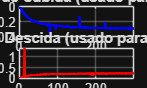


figure('Name','Respostas Médias a Degrau');
subplot(2,1,1); plot(time_up, avg_step_up, 'b', 'LineWidth', 1.5); title('Degrau Médio de Subida (usado para VALIDAÇÃO)'); xlabel('Tempo (s)'); ylabel('Amplitude'); grid on;
subplot(2,1,2); plot(time_down, avg_step_down, 'r', 'LineWidth', 1.5); title('Degrau Médio de Descida (usado para IDENTIFICAÇÃO)'); xlabel('Tempo (s)'); ylabel('Amplitude'); grid on;

## 5. Identificação do Modelo com o Método de Smith



y_model = avg_step_down;
time_model = time_down;
if length(y_model) > 4, y_model(1:3) = y_model(4); end
steady_state_start_index = round(0.9 * length(y_model));
K_model = mean(y_model(steady_state_start_index:end));
K_system = -K_model;
y20 = 0.20 * K_model;
y60 = 0.60 * K_model;
idx20 = find(y_model >= y20, 1, 'first');
idx60 = find(y_model >= y60, 1, 'first');
if isempty(idx20) || isempty(idx60), error('Não foi possível encontrar 20% e 60% na curva.'); end
t20 = time_model(idx20);
t60 = time_model(idx60);
ratio_t20_t60 = t20 / t60;

% =========================================================================
% ==                AÇÃO DO USUÁRIO: PREENCHA OS VALORES DO GRÁFICO      ==
% =========================================================================
% Usando a razão t20/t60 = 0.7143, encontre os seguintes valores nos gráficos de Smith:

ratio_t60_tau_do_grafico = 1.8; % <--- SUBSTITUA ESTE VALOR pelo que você leu no gráfico t60/τ
zeta_do_grafico = 1.5;         % <--- SUBSTITUA ESTE VALOR pelo que você leu no gráfico de ζ

% =========================================================================
tau = t60 / ratio_t60_tau_do_grafico;
s = tf('s');
G_s = K_system / (tau^2 * s^2 + 2 * tau * zeta_do_grafico * s + 1);

fprintf('\n--- Função de Transferência Identificada ---\n');


--- Função de Transferência Identificada ---


G_s


G_s =
 
         -0.2229
  ----------------------
  60.5 s^2 + 23.33 s + 1
 
Continuous-time transfer function.


## 6. Validação do Modelo

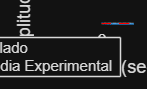


figure('Name','Validação do Modelo');
step(G_s, time_up(end));
hold on;
plot(time_up, avg_step_up, '--r', 'LineWidth', 1.5);
title('Validação do Modelo - Resposta a Degrau de Subida');
xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Modelo Simulado', 'Resposta Média Experimental'); grid on;

## 7. Projeto do Filtro Passa-Baixas


fprintf('\n--- Projeto do Filtro Butterworth de 2ª Ordem ---\n');


--- Projeto do Filtro Butterworth de 2ª Ordem ---



% 7.1. Estimar a banda (-3dB) do processo a partir do modelo
% Usamos o ganho positivo para a função 'bandwidth'
G_s_positivo = abs(K_system) / (tau^2 * s^2 + 2 * tau * zeta_do_grafico * s + 1);
wb_processo = bandwidth(G_s_positivo); % Largura de banda em rad/s
fprintf('Largura de banda estimada do processo (wb): %.4f rad/s\n', wb_processo);

Largura de banda estimada do processo (wb): 0.0480 rad/s



% 7.2. Definir a frequência de corte do filtro (wc)
% Conforme a especificação, wc deve ser bem maior que wb. Usaremos um fator de 10.
fator_separacao = 10;
wc_filtro = fator_separacao * wb_processo;
fprintf('Frequência de corte do filtro definida (wc): %.4f rad/s (%.1f x wb)\n', wc_filtro, fator_separacao);

Frequência de corte do filtro definida (wc): 0.4800 rad/s (10.0 x wb)



% 7.3. Projetar o filtro Butterworth digital
% Precisamos da frequência de amostragem média
fs = 1 / mean(diff(time_s)); % Frequência de amostragem média em Hz
nyquist_freq_rads = fs * pi; % Frequência de Nyquist em rad/s

% Normaliza a frequência de corte para a função 'butter' (0 a 1)
Wn = wc_filtro / nyquist_freq_rads;
n_ordem = 2; % Ordem do filtro
[b, a] = butter(n_ordem, Wn, 'low');
fprintf('Filtro Butterworth de %dª ordem projetado.\n', n_ordem);

Filtro Butterworth de 2ª ordem projetado.


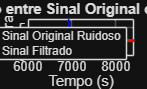


% 7.4. Aplicar o filtro ao sinal original e ruidoso
output_filtrado = filter(b, a, output);

% Plota o resultado da filtragem
figure('Name', 'Efeito do Filtro Passa-Baixas');
plot(time_s, output, 'b-', 'DisplayName', 'Sinal Original Ruidoso');
hold on;
plot(time_s, output_filtrado, 'r-', 'LineWidth', 2, 'DisplayName', 'Sinal Filtrado');
title('Comparação entre Sinal Original e Sinal Filtrado');
xlabel('Tempo (s)');
ylabel('Leitura');
legend;
grid on;

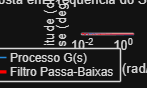


% 7.5. Análise em Frequência (Prova Conceitual)
figure('Name', 'Análise em Frequência');
bode_opts = bodeoptions;
bode_opts.FreqUnits = 'rad/s';
bode(G_s_positivo, bode_opts); % Plota a resposta do sistema
hold on;
[h, w] = freqz(b, a, 2048, fs); % Obtém a resposta do filtro
plot(w*2*pi, 20*log10(abs(h)), 'r', 'LineWidth', 2); % Plota a magnitude do filtro
title('Resposta em Frequência do Sistema e do Filtro');
legend('Processo G(s)', 'Filtro Passa-Baixas');
grid on;
xlim([1e-2, nyquist_freq_rads]);

## 8 Análises dinâmicas com o Filtro de Butterworth


% 8.1 Visualização do modelo dinâmico da planta

fprintf('Função de Transferência da Planta (em tempo contínuo):\n');

Função de Transferência da Planta (em tempo contínuo):


G_s


G_s =
 
         -0.2229
  ----------------------
  60.5 s^2 + 23.33 s + 1
 
Continuous-time transfer function.


disp(G_s);

  tf with properties:

       Numerator: {[0 0 -0.2229]}
     Denominator: {[60.4958 23.3337 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




fprintf('Função de Transferência da Planta (em tempo contínuo, sinal invertido):\n');

Função de Transferência da Planta (em tempo contínuo, sinal invertido):


G_s_positivo


G_s_positivo =
 
          0.2229
  ----------------------
  60.5 s^2 + 23.33 s + 1
 
Continuous-time transfer function.


disp(G_s_positivo);

  tf with properties:

       Numerator: {[0 0 0.2229]}
     Denominator: {[60.4958 23.3337 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Função de Transferência do Filtro Passa-Baixas (em tempo contínuo):
  tf with properties:

       Numerator: {[0 0 1.6530e-04]}
     Denominator: {[1 0.0182 1.6530e-04]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



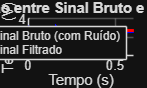

Função de Transferência do Filtro Passa-Baixas (em tempo contínuo):
  tf with properties:

       Numerator: {[0 0 1.6530e-04]}
     Denominator: {[1 0.0182 1.6530e-04]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]

Função de Transferência do Filtro Passa-Baixas (em tempo discreto):
  tf with properties:

       Numerator: {[0 2.0600e-05 2.0538e-05]}
     Denominator: {[1 -1.9909 0.9909]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGr


% 8.2 Visualização do modelo dinâmico do filtro

run("./filtro.m");


fprintf('Função de transferência do Filtro de Butterworth (em tempo contínuo):\n');

Função de transferência do Filtro de Butterworth (em tempo contínuo):


H_s


H_s =
 
           0.0001653
  ---------------------------
  s^2 + 0.01818 s + 0.0001653
 
Continuous-time transfer function.


disp(H_s);

  tf with properties:

       Numerator: {[0 0 1.6530e-04]}
     Denominator: {[1 0.0182 1.6530e-04]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




fprintf('Função de Transferência do Filtro de Butterworth (em tempo discreto):\n');

Função de Transferência do Filtro de Butterworth (em tempo discreto):


H_z


H_z =
 
  2.06e-05 z + 2.054e-05
  ----------------------
  z^2 - 1.991 z + 0.9909
 
Sample time: 0.5 seconds
Discrete-time transfer function.


disp(H_z);

  tf with properties:

       Numerator: {[0 2.0600e-05 2.0538e-05]}
     Denominator: {[1 -1.9909 0.9909]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0.5000
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




fprintf('Feedback da planta com o Filtro de Butterworth (resposta em tempo discreto):\n\n');

Feedback da planta com o Filtro de Butterworth (resposta em tempo discreto):



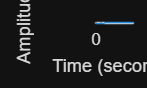

G_s_positivo = tf(G_s_positivo.Numerator, G_s_positivo.Denominator);
G_z_positivo = c2d(G_s_positivo, Ts, 'zoh');
sys_fb = feedback(H_z * G_z_positivo, 1);
step(sys_fb);

## 9 Simulação do modelo dinâmico em Simulink



run("./simulink_constants.m");


## 10 Projeto dos controladores

% Definição baseada no modelo explicado no roteiro

%tau_c_desejado = 1;
tau_c_desejado = 0.7;
K_planta = 1;
tau_1_planta = 1;
tau_2_planta = 0.1;

Kp_s1 = (tau_1_planta + tau_2_planta)/(K_planta * tau_c_desejado);
Ti_s1 = tau_1_planta + tau_2_planta;
Td_s1 = (tau_1_planta * tau_2_planta)/(tau_1_planta + tau_2_planta);
Kd_s1 = K_planta * tau_c_desejado;

Kp_s2 = (3 * tau_1_planta * tau_2_planta - tau_c_desejado^2)/(K_planta * tau_c_desejado^2);
Ti_s2 = tau_c_desejado * (3 * tau_1_planta * tau_2_planta - tau_c_desejado^2)/(tau_1_planta * tau_2_planta);
Td_s2 = tau_c_desejado * (3 * tau_1_planta * tau_2_planta - (tau_1_planta + tau_2_planta) * tau_c_desejado)/(3 * tau_1_planta * tau_2_planta - tau_c_desejado^2);
Kd_s2 = K_planta * (tau_c_desejado^3)/(tau_1_planta * tau_2_planta);

%kp = Kp_s1;
kp = Kp_s2;
%ti = Ti_s1;
ti = Ti_s2;
%td = Td_s1;
td = Td_s2;



% =========================================================================
% ==                DEFINIÇÃO DAS FUNÇÕES LOCAIS                       ==
% =========================================================================

function [avg_y, time_uniform] = average_responses(responses_y, responses_t)
    min_duration = min(cellfun(@(t) t(end), responses_t));
    avg_dt = mean(cellfun(@(t) mean(diff(t)), responses_t));
    time_uniform = (0:avg_dt:min_duration)';
    resampled_y = zeros(length(time_uniform), length(responses_y));
    for k = 1:length(responses_y)
        resampled_y(:, k) = interp1(responses_t{k}, responses_y{k}, time_uniform, 'linear', 'extrap');
    end
    avg_y = mean(resampled_y, 2);
end